% load('/Users/marissa/Documents/Landy Lab/perturbExperiment/data_perturb/MF/MF_perturb_exp_S1_2023-01-24_16-05_controlresults.mat')
% load('/Users/marissa/Documents/Landy Lab/perturbExperiment/data_perturb/MF/MF_perturb_exp_S1_2023-01-24_16-05_dispInfo.mat')

% reaches = [contResultsMat.pktData(:,1),contResultsMat.pktData(:,2)];
% [reaches(:,1), reaches(:,2)] = transformPointsForward(tformMM,reaches(:,1),reaches(:,2));
% 
% [target1(1), target1(2)] = (transformPointsForward(invtform,contResultsMat.targetLoc(1),contResultsMat.targetLoc(2)));
% [target1(1), target1(2)] = (transformPointsForward(tformMM,target1(1),target1(2)));
% 
% indicated = [contResultsMat.mouseEndPt(61:end,1),contResultsMat.mouseEndPt(61:end,2)];
% [indicated(:,1), indicated(:,2)] = (transformPointsForward(tformMM,indicated(:,1),indicated(:,2)));
%             
% data = contResultsMat.pktData;
% data(:,1:2) = reaches;
% startPosidx = (data(:,5) == 0)+1;
% startPos = mean(data(startPosidx,1:2))
% data(:,1:2) = (data(:,1:2) - startPos);
% target1 = target1-startPos;
% indicated = indicated-startPos

% figure; hold on
% for ii = 61:360
%     idx = data(:,6) == ii;
%     x = data(idx,1);
%     y = data(idx,2);
%     plot(x,y)
%     scatter(indicated(ii-60,1),indicated(ii-60,2),10,'b','filled')
% end
% scatter(target1(1),target1(2),20,'r','filled')
% axis equal

load('/Users/mhe229/Documents/Landy Lab/perturbExperiment/data_perturb/SM/SM_perturb_exp_S0_2023-09-25_11-15_results.mat')
load('/Users/mhe229/Documents/Landy Lab/perturbExperiment/data_perturb/SM/SM_perturb_exp_S0_2023-09-25_11-15_dispInfo.mat')

%% Creating transforms from calibration

%Inverse transform to get from pixel to tablet space
invtform = invert(displayInfo.tform);           %Inverse transformation from participant's calibration

%Creating a matrix for the calibration points in tablet space
wacX = displayInfo.calibration{1,6};
wacY = displayInfo.calibration{1,7};
wac = [wacX' wacY'];

%Calibration point locations in mm measurments from edge of tablet active
%area
mmWacSpace = [23,244; 23,134; 23,27; 238,244; 238,134; 238,27; 446, 244; 446,134; 446,27;];

%affine transform from tablet space to mm
M = affine_least_square(wac(2,1),wac(2,2),wac(5,1),wac(5,2),wac(6,1),wac(6,2), mmWacSpace(2,1),mmWacSpace(2,2),mmWacSpace(5,1),mmWacSpace(5,2),mmWacSpace(6,1),mmWacSpace(6,2));
tformMM = affine2d(M');

%Isolate reaches
reaches = [resultsMat.pktData(:,1),resultsMat.pktData(:,2);];
[reaches(:,1), reaches(:,2)] = transformPointsForward(tformMM,reaches(:,1),reaches(:,2));
            
data2 = [resultsMat.pktData;];
data2(:,1:2) = reaches;

%Find starting postion to center data
[startPos(:,1), startPos(:,2)] = (transformPointsForward(invtform,resultsMat.startPos(:,1),resultsMat.startPos(:,2))); %transform target locations into wacom space
[startPos(:,1), startPos(:,2)] = transformPointsForward(tformMM,startPos(:,1),startPos(:,2));
            
data2(:,1:2) = (data2(:,1:2) - startPos);

%isolate target postions and center
target = [resultsMat.targetLoc(:,1),resultsMat.targetLoc(:,2);];
[target(:,1), target(:,2)] = (transformPointsForward(invtform,target(:,1),target(:,2))); %transform target locations into wacom space
[target(:,1), target(:,2)] = transformPointsForward(tformMM,target(:,1),target(:,2));
target = target-startPos;

%Isolate endpionts and center
endPts = [resultsMat.wacEndPoint;];
[endPts(:,1), endPts(:,2)] = transformPointsForward(tformMM,endPts(:,1),endPts(:,2));
endPts = endPts - startPos;

%Isolate perturbed locations and center
ptbLoc = [resultsMat.feedbackLoc(:,1),resultsMat.feedbackLoc(:,2);];
[ptbLoc(:,1), ptbLoc(:,2)] = (transformPointsForward(invtform,ptbLoc(:,1), ptbLoc(:,2))); %transform target locations into wacom space
[ptbLoc(:,1), ptbLoc(:,2)] = transformPointsForward(tformMM,ptbLoc(:,1),ptbLoc(:,2));
ptbLoc = ptbLoc-startPos;

%Confidence
confRad = [resultsMat.confRad;];
xCen = 237.4199; 
for jj = 1:length(confRad)
    temp = confRad(jj);
    [temp1, temp2] = transformPointsForward(invtform,temp+displayInfo.xCenter,displayInfo.yCenter);
    confCirc(jj,:) = (transformPointsForward(tformMM,temp1,temp2))-xCen;
end

x = 1:384;
cTrial = confCirc>.0001;
ptb = displayInfo.ptb;
ptb = repmat(ptb,[1,6]);
ptb = ptb~=0;
ptbOrder = [displayInfo.ptbOrder];
% 1= rotate left
% 2 = rotate right
% 3 = shift left
% 4 = shift right
% 5 = plus gain
% 6 = minus gain
endTemp = [];
tarTemp = [];
confTemp = [];
ptbTemp = [];
dataTemp = [];

sessions = [0    64   128   192   256   320];
for ii = 1:6
    x = ptbOrder == ii;
    s = sessions(x);
    ep = endPts(s+1:s+64,:);
    endTemp = [endTemp; ep];
    tar = target(s+1:s+64,:);
    tarTemp = [tarTemp; tar];
    p = ptbLoc(s+1:s+64,:);
    ptbTemp = [ptbTemp; p];
    c = confCirc(s+1:s+64,:);
    confTemp  = [confTemp; c];
    d = data2(s+1:s+64,:);
    dataTemp = [dataTemp; d];

end
confCirc = confTemp;
endPts = endTemp;
ptbLoc = ptbTemp;
target = tarTemp;
data2 = dataTemp;
ptbOrder = [1 2 3 4 5 6];

ptbDist = sqrt((ptbLoc(:,1) - target(:,1)).^2 + (ptbLoc(:,2)-target(:,2)).^2);
endDist = sqrt((endPts(:,1) - target(:,1)).^2 + (endPts(:,2)-target(:,2)).^2);
reachDist = sqrt((endPts(:,1) - 0).^2 + (endPts(:,2)-0).^2);

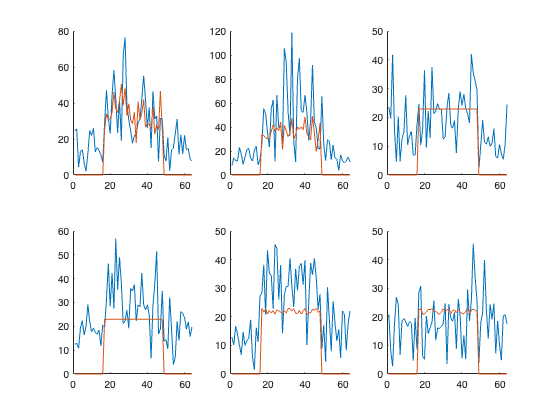

% 1. rotate points to align perturbation direction 
% 2. Find the error perpindicular to the perterbation
% 3. Find error parallel to the perterbation
% 4. sqrt(error_perp^2 + (error_para+pert)^2)
% 5. compare across all types of perterbations 
sessions = [0    64   128   192   256   320];
errorVol = [];
ptbOrdered = [];
confOrdered = [];
figure
for ii = 1:6
    x = ptbOrder == ii;
    s = sessions(x);
    ep = endPts(s+1:s+64,:);
    tar = target(s+1:s+64,:);
    pLoc = ptbLoc(s+1:s+64,:);
    ptbAmount = sqrt((pLoc(:,1) - ep(:,1)).^2 + (pLoc(:,2)-ep(:,2)).^2);
    confTemp = confCirc(s+1:s+64,1);
    if ii == 1
        rotatePt = [0,-1];
        for tt = 1:length(ep)

            %Finding the angle from the starting point, the center of the tablet,
            %and the target location
            cosTheta = dot(ep(tt,:),rotatePt)/((sqrt((0 - ep(tt,1))^2 + (0-ep(tt,2))^2))*(sqrt((0 - rotatePt(1))^2 + (0-rotatePt(2))^2)));
            theta = real(acosd(cosTheta));

            %choose if rotation is clockwise or counter clockwise
            if target(tt,1) <= 0
                R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
            else
                R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
            end

            tar2(tt,:) = (R*(tar(tt,:)'))';

            %rotate data points by target angle then shift by difference in Y
            shifted(tt,:) = R*(ep(tt,:)');
            %shifted2(tt,:) = R*(pLoc(tt,:)');
        end
        ep2 = shifted'-tar2';
        %pL2 = shifted2'-tar2';
    elseif ii == 2
        rotatePt = [0,1];
        for tt = 1:length(ep)

            %Finding the angle from the starting point, the center of the tablet,
            %and the target location
            cosTheta = dot(ep(tt,:),rotatePt)/((sqrt((0 - ep(tt,1))^2 + (0-ep(tt,2))^2))*(sqrt((0 - rotatePt(1))^2 + (0-rotatePt(2))^2)));
            theta = real(acosd(cosTheta));

            %choose if rotation is clockwise or counter clockwise
            if target(tt,1) <= 0
                R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
            else
                R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
            end

            tar2(tt,:) = (R*(tar(tt,:)'))';

            %rotate data points by target angle then shift by difference in Y
            shifted(tt,:) = R*(ep(tt,:)');
            %shifted2(tt,:) = R*(pLoc(tt,:)');
        end
        ep2 = shifted'-tar2';
        %pL2 = shifted2'-tar2';
    elseif ii == 3
        theta = 180;
        shifted = ep-tar;
        %shifted2 = pLoc - tar;
        R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
        ep2 = R*(shifted');
        %pL2 = R*(shifted2');
    elseif ii == 4
        theta = 0;
        shifted = ep-tar;
        %shifted2 = pLoc - tar;
        R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
        ep2 = R*(shifted');
        %pL2 = R*(shifted2');
    elseif ii == 5
        theta = 90;
        shifted = ep-tar;
        %shifted2 = pLoc - tar;
        R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
        ep2 = R*(shifted');
        %pL2 = R*(shifted2');
    elseif ii == 6
        theta = 270;
        shifted = ep-tar;
        %shifted2 = pLoc - tar;
        R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
        ep2 = R*(shifted');
        %pL2 = R*(shifted2');
    end
    
    %ptbErrTemp = sqrt(ep2(2,:).^2+ep2(1,:).^2);
    errTemp = sqrt(ep2(2,:).^2+(ep2(1,:)+ptbAmount').^2);
    errorVol = [errorVol; errTemp'];
    ptbOrdered = [ptbOrdered; ptbAmount];
    confOrdered = [confOrdered; confTemp];
    subplot(2,3,ii); hold on
    plot(errTemp)
    plot(ptbAmount)
end

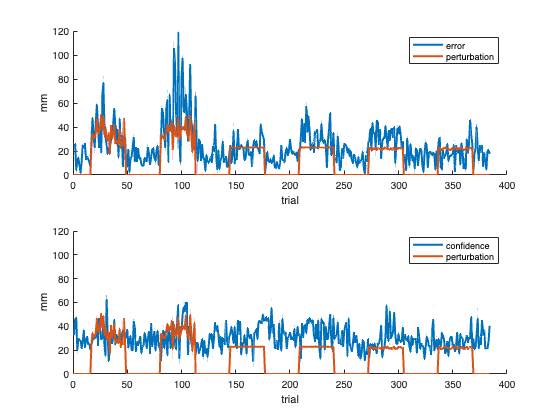



figure
subplot(2,1,1); hold on
plot(errorVol,'LineWidth',2)
plot(ptbOrdered,'LineWidth',2)
legend('error','perturbation')
ylabel('mm')
xlabel('trial')
ylim([0 120])

subplot(2,1,2);hold on
plot(confOrdered,'LineWidth',2)
plot(ptbOrdered,'LineWidth',2)
legend('confidence','perturbation')
ylabel('mm')
xlabel('trial')
ylim([0 120])

%perturbation Locations if PERFECT performance- after points rotated to
%center on target. (where aiming location should be if target was hit)
% ptbAngle = 20;
% ptbSize = 23;
% rotStart = [0,-100];
% sessions = [0    64   128   192   256   320];
% 
% for bb = 1:6
%     if ptbOrder(bb) == 1 %rotate left
%         xPtb(:,bb) = (endPts(:,1)-rotStart(1)).*cosd(ptbAngle)-(endPts(:,2)-rotStart(2)).*sind(ptbAngle)+rotStart(1);
%         yPtb(:,bb) = (endPts(:,1)-rotStart(1)).*sind(ptbAngle)+(endPts(:,2)-rotStart(2)).*cosd(ptbAngle)+rotStart(2);
% 
%     elseif ptbOrder(bb) == 2 %rotate right
%         xPtb(:,bb) = (endPts(:,1)-rotStart(1)).*cosd(ptbAngle)+(endPts(:,2)-rotStart(2)).*sind(ptbAngle)+rotStart(1);
%         yPtb(:,bb) = -(endPts(:,1)-rotStart(1)).*sind(ptbAngle)+(endPts(:,2)-rotStart(2)).*cosd(ptbAngle)+rotStart(2);
% 
%     elseif ptbOrder(bb) == 3 %shift left
%         xPtb(:,bb) = endPts(:,1)-ptbSize;
%         yPtb(:,bb) = endPts(:,2);
% 
%     elseif ptbOrder(bb) == 4 %shift right
%         xPtb(:,bb) = endPts(:,1)+ptbSize;
%         yPtb(:,bb) = endPts(:,2);
% 
%     elseif ptbOrder(bb) == 5 %plus gain
%         lenReach = sqrt(sum((endPts - rotStart).^2));
%         endPt2 = endPts - rotStart;
%         unitReach = endPt2/lenReach;
%         newLen = lenReach + ptbSize;
%         plusGain = (unitReach*newLen) + rotStart;
%         xPtb(:,bb) = plusGain(1);
%         yPtb(:,bb) = plusGain(2);
% 
%     elseif ptbOrder(bb) == 6 %minus gain
%         lenReach = sqrt(sum((endPts - rotStart).^2));
%         endPt2 = endPts -rotStart;
%         unitReach = endPt2/lenReach;
%         newLen = lenReach - ptbSize;
%         minusGain = (unitReach*newLen) + rotStart;
%         xPtb(:,bb) = minusGain(1);
%         yPtb(:,bb) = minusGain(2);
%     end
% end

% %Rotate points to center coordinates
% rotatePt = [0,100];
% trajShift = [];
% 
% for tt = 1:length(target)
% 
%     %Finding the angle from the starting point, the center of the tablet,
%     %and the target location
%     cosTheta = dot(target(tt,:),rotatePt)/((sqrt((0 - target(tt,1))^2 + (0-target(tt,2))^2))*(sqrt((0 - 0)^2 + (0-100)^2)));
%     theta = real(acosd(cosTheta));
% 
%     %choose if rotation is clockwise or counter clockwise
%     if target(tt,1) <= 0
%         R = [cosd(theta) sind(theta); -sind(theta) cosd(theta)];
%     else
%         R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
%     end
% 
%     % Rotate target points
%     targetShift(tt,:) = (R*(target(tt,:)'))'; % + startPos';
% 
%     %Collapse across y space
%     yShift = targetShift(tt,2);
% 
%     %rotate data points by target angle then shift by difference in Y
%     endPtsShift(tt,:) = R*(endPts(tt,:)') - [0; yShift];
% 
%     %rotate perturbed feedback by target angle then shift by Y
%     ptbShift(tt,:) = R*(ptbLoc(tt,:)') - [0; yShift];
% 
%     %Rotate trajectories 
%     idx = data2(:,7) == tt;
%     traj = data2(idx,1:2);
%     for ii = 1:length(traj)
%         trajTemp(ii,1:2) = R*(traj(ii,:)') - [0; yShift];
%         trajTemp(ii,3) = tt;
%     end
%     trajShift = [trajShift; trajTemp];
%     clear trajTemp
% end


% %Plotting rotated endpoints
% figure; hold on
% scatter(endPtsShift(:,1),endPtsShift(:,2))
% scatter(ptbShift(:,1),ptbShift(:,2))
% 
% %Plotting rotated trajectories
% figure; hold on
% for tt = 1:length(target)
%     x1 = trajShift(trajShift(:,3) == tt,1);
%     y1 = trajShift(trajShift(:,3) == tt,2);
%     plot(x1,y1)
% end

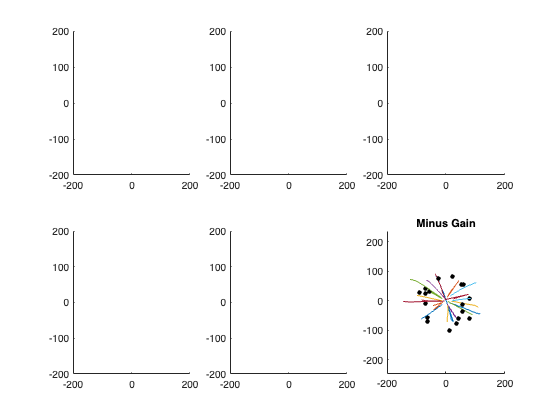

%Plot of each trajectory for every perturbation block type (NOT rotated)
sessions = [0    64   128   192   256   320   384];
ptbType = [{'Rotate Left'},{'Rotate Right'},{'Shift Left'},{'Shift Right'},{'Plus Gain'},{'Minus Gain'}];
figure
for jj = 1:6
    subplot(2,3,jj); hold on
    idx = data2(:,6) == jj;
    x = data2(idx,1);
    y = data2(idx,2);
    trial = data2(idx,7);
    for ii = min(trial):max(trial)
        idx2 = trial == ii;
        x2 = x(idx2);
        y2 = y(idx2);
        plot(x2,y2)
        scatter(target(ii,1),target(ii,2),20,'k','filled')
        title([ptbType{jj}])
    end
    xlim([-200 200])
    ylim([-200 200])
end
axis equal

% %Plot of each trajectory for every perturbation block type (ROTATED)
% sessions = [0    64   128   192   256   320   384];
% ptbType = [{'Rotate Left'},{'Rotate Right'},{'Shift Left'},{'Shift Right'},{'Plus Gain'},{'Minus Gain'}];
% figure
% for jj = 1:6
%     subplot(2,3,jj); hold on
%     idx = data2(:,6) == jj;
%     x = trajShift(idx,1);
%     y = trajShift(idx,2);
%     trial = data2(idx,7);
%     count = 0;
%     for ii = min(trial):max(trial)
%         count = count+1;
%         idx2 = trial == ii;
%         x2 = x(idx2);
%         y2 = y(idx2);
%         if count <=17
%             plot(x2,y2,'r')
%         elseif count <=48
%             plot(x2,y2,'b')
%         else
%             plot(x2,y2,'m')
%         end
%     end
%     %scatter(xPtb(ptbOrder == jj),yPtb(ptbOrder == jj),20,'g','filled')
%     scatter(0,0,20,'k','filled')
%     title([ptbType{jj}])
%     xlim([-200 200])
%     ylim([-200 200])
% end
% axis equal


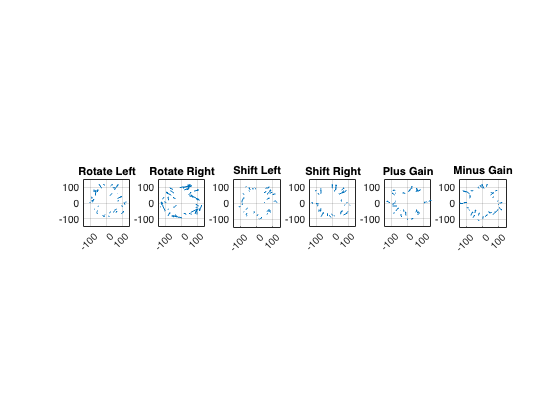

%Comparing error direction during and before/after perturbation
sessions = [0    64   128   192   256   320];
ptbType = [{'Rotate Left'},{'Rotate Right'},{'Shift Left'},{'Shift Right'},{'Plus Gain'},{'Minus Gain'}];
rq = [];
rp = [];
figure
for ii = 1:6
    x = ptbOrder == ii;
    s = sessions(x);
    p1 = [target(17+s:48+s,:);target(17+s:48+s,:)];                         % First Point
    p2 = [endPts(17+s:48+s,:);endPts(17+s:48+s,:)];                         % Second Point
    dp = p2-p1;                         % Difference
    
    subplot(1,6,ii)
    quiver(p1(:,1),p1(:,2),dp(:,1),dp(:,2),0)
    grid
    xlim([-150 150])
    ylim([-150 150])
    xticks([-100 0 100])
    yticks([-100 0 100])
    title(ptbType(ptbOrder(ii)))
    axis square

    
end

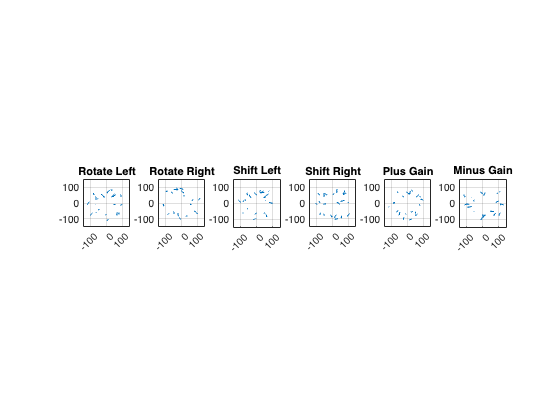


figure
for ii = 1:6
x = ptbOrder == ii;
    s = sessions(x);
    r1 = [target([s+1:s+10,s+55:s+64],:);target([s+1:s+10,s+55:s+64],:)];
    r2 = [endPts([s+1:s+10,s+55:s+64],:);endPts([s+1:s+10,s+55:s+64],:)];
    r3 = r1-r2;
    rq = [rq;r1];
    rp = [rp;r3];
subplot(1,6,ii)
    quiver(r1(:,1),r1(:,2),r3(:,1),r3(:,2),0)
    grid
    xlim([-150 150])
    ylim([-150 150])
    xticks([-100 0 100])
    yticks([-100 0 100])
    title(ptbType(ptbOrder(ii)))
    axis square
end 

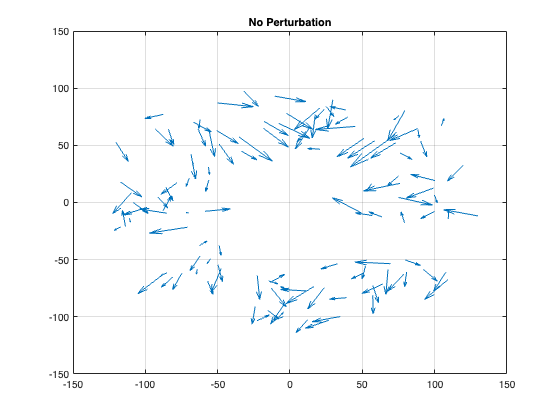

figure
quiver(rq(:,1),rq(:,2),rp(:,1),rp(:,2),0)
grid
xlim([-150 150])
ylim([-150 150])
title('No Perturbation')

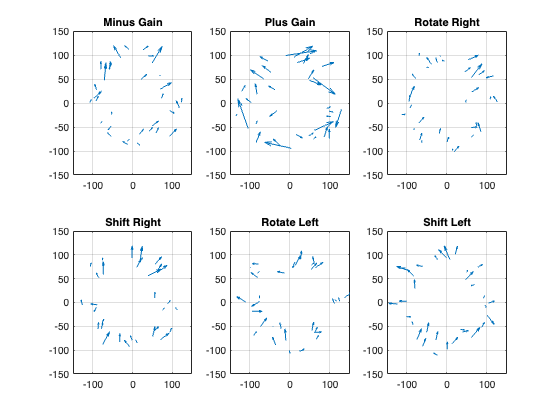

%Plotting only changes DURING perturbation
sessions = [0    64   128   192   256   320];
ptbType = [{'Rotate Left'},{'Rotate Right'},{'Shift Left'},{'Shift Right'},{'Plus Gain'},{'Minus Gain'}] ;
figure
for ii = 1:6
    
    p1 = target(17+sessions(ii):48+sessions(ii),:);                         % First Point
    p2 = endPts(17+sessions(ii):48+sessions(ii),:);                         % Second Point
    dp = p2-p1;                         % Difference
    
    subplot(2,3,ii)
    quiver(p1(:,1),p1(:,2),dp(:,1),dp(:,2),0)
    grid
    xlim([-150 150])
    ylim([-150 150])
    title(ptbType(displayInfo.ptbOrder(ii)))
end

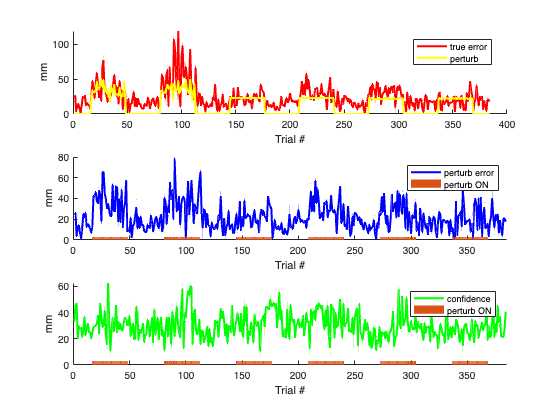

%Plotting bar graphs of changes in data over trials
captured = resultsMat.pointsEarned~=0;
x = 1:384;
figure; hold on
subplot(3,1,1); hold on
plot(x,errorVol,'r','LineWidth',2)
plot(ptbOrdered,'y','LineWidth',2)
legend('true error','perturb','location','best')
xlabel('Trial #')
ylabel('mm')

subplot(3,1,2); hold on
plot(x,ptbDist,'b','LineWidth',2)
bar(x,ptb*3)
legend('perturb error','perturb ON','location','best')
xlabel('Trial #')
ylabel('mm')

subplot(3,1,3); hold on
plot(x,confCirc,'g','LineWidth',2)
bar(x,ptb*3)
legend('confidence','perturb ON','location','best')
xlabel('Trial #')
ylabel('mm')

%Separate changes in x and y error shifts
% ordered = [];
% ptbx = double(ptb);
% ptby = double(ptb);
% 
% for ii = 1:6
%     x = ptbOrder == ii;
%     s = sessions(x);
%     s1 = sessions(ii);
%     ptbx(s1+1:s1+64)=ptbx(s1+1:s1+64)*xPtb(x);
%     ptby(s1+1:s1+64)=ptby(s1+1:s1+64)*yPtb(x);
%     ordered = [ordered;endPtsShift(s+1:s+64,:)];
% end
% 
% figure
% subplot(2,1,1); hold on
% plot(ordered(:,1))
% plot(ptbx)
% title('x-axis error')
% legend('data','perturbation')
% ylim([-80 80])
% ylabel('mm')
% 
% subplot(2,1,2); hold on
% plot(ordered(:,2))
% plot(ptby)
% title('y-axis error')
% legend('data','perturbation')
% ylim([-80 80])
% ylabel('mm')


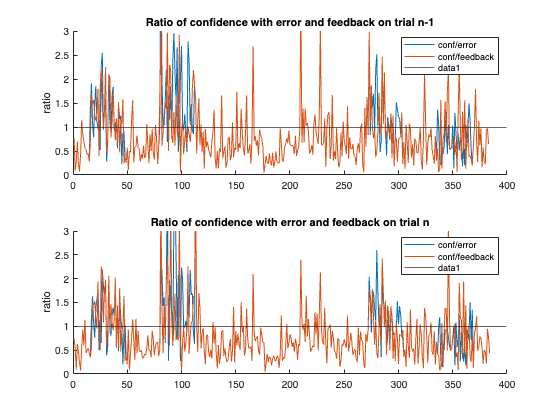

%Ratio of confidence over true error and feedback error

figure
% difConf = confCirc(2:end)./endDist(1:end-1);
% difFeed = confCirc(2:end)./ptbDist(1:end-1);

difConf = errorVol(2:end)./confCirc(1:end-1);
difFeed = ptbDist(2:end)./confCirc(1:end-1);
subplot(2,1,1); hold on
plot(difConf)
plot(difFeed)
%bar(ptb)
ylabel('ratio')
legend('conf/error','conf/feedback')
title('Ratio of confidence with error and feedback on trial n-1')
ylim(([0 3]))
yline(1);

subplot(2,1,2); hold on
difConf = errorVol./confCirc;
difFeed = ptbDist./confCirc;
plot(difConf)
plot(difFeed)
%bar(ptb)
ylabel('ratio')
legend('conf/error','conf/feedback')
title('Ratio of confidence with error and feedback on trial n')
ylim(([0 3]))
yline(1)

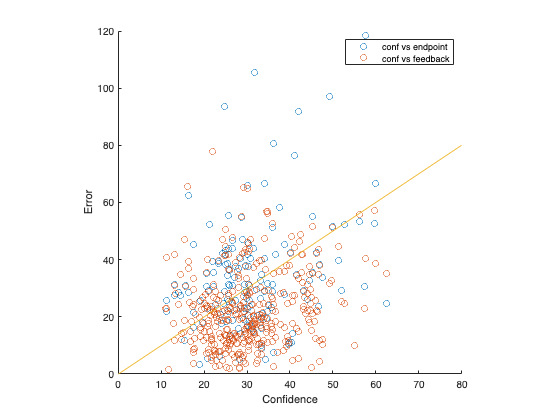

%scatterplot of confidence vs true and perturbed endpoints
figure; hold on
scatter(confCirc,errorVol)
scatter(confCirc,ptbDist)
plot(0:80,0:80)
legend('conf vs endpoint','conf vs feedback')
axis square
xlabel('Confidence')
ylabel('Error')

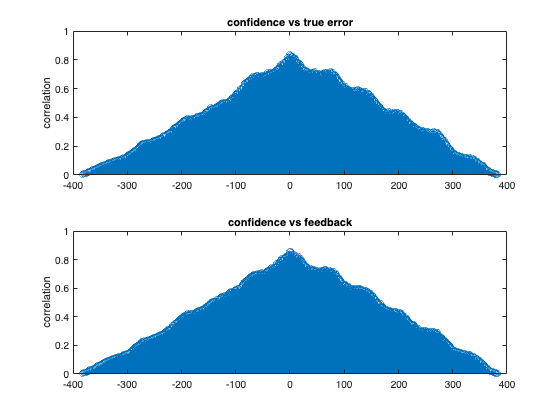

%Cross correlation between confidence, error and feedback
figure
[c,lags] = xcorr(confCirc,errorVol,'normalized');
subplot(2,1,1)
stem(lags,c)
ylim([0 1])
ylabel('correlation')
title('confidence vs true error')

[c,lags] = xcorr(confCirc,ptbDist,'normalized');
subplot(2,1,2)
stem(lags,c)
ylim([0 1])
title('confidence vs feedback')
ylabel('correlation')

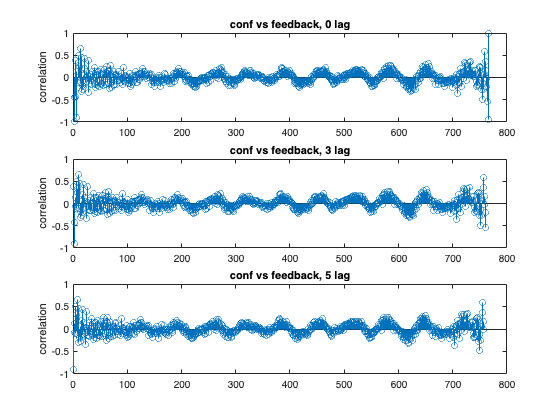

%Sliding cross correlation confidence with feedback

figure
subplot(3,1,1)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,ptbDist,0);
stem(r)
ylim([-1 1])
title('conf vs feedback, 0 lag')
ylabel('correlation')

subplot(3,1,2)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,ptbDist,3);
stem(r)
ylim([-1 1])
title('conf vs feedback, 3 lag')
ylabel('correlation')

subplot(3,1,3)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,ptbDist,5);
stem(r)
ylim([-1 1])
title('conf vs feedback, 5 lag')
ylabel('correlation')

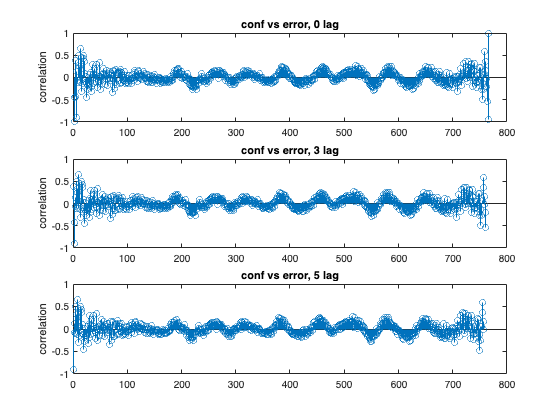

%Sliding cross correlation confidence with error
figure
subplot(3,1,1)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,errorVol,0);
stem(r)
ylim([-1 1])
title('conf vs error, 0 lag')
ylabel('correlation')

subplot(3,1,2)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,errorVol,3);
stem(r)
ylim([-1 1])
title('conf vs error, 3 lag')
ylabel('correlation')

subplot(3,1,3)
[r, lag] = slidingCrossCorrelationCoefficient(confCirc,errorVol,5);
stem(r)
ylim([-1 1])
title('conf vs error, 5 lag')
ylabel('correlation')

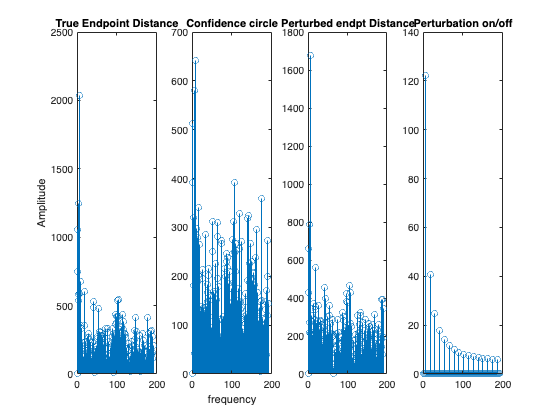

%seeing if the perturbation frequency is calucalable in the data
nsamp = length(ptb);
xShift = (0:nsamp/2-1);

transf1 = fftshift(abs(fft(errorVol)));
transf1(transf1 == max(transf1)) = 0;

transf2 = fftshift(abs(fft(confCirc)));
transf2(transf2 == max(transf2)) = 0;

transf3 = fftshift(abs(fft(ptbDist)));
transf3(transf3 == max(transf3)) = 0;

transf4 = fftshift(abs(fft(ptb)));
transf4(transf4 == max(transf4)) = 0;

figure
subplot(1,4,1)
stem(xShift,transf1(193:end))
title('True Endpoint Distance')
ylabel('Amplitude')

subplot(1,4,2)
stem(xShift,transf2(193:end))
title('Confidence circle')
xlabel('frequency')

subplot(1,4,3)
stem(xShift,transf3(193:end))
title('Perturbed endpt Distance')

subplot(1,4,4)
stem(xShift,transf4(193:end))
title('Perturbation on/off')

% % Fitting curves to the data??
% figure
% for ii = 1:6
%     p = ptbOrder == ii;
%     s = sessions(p);
%     y = [endDist(s+1:64+s,:);endDist(1+s:64+s,:)];                         % First Point
%     x = 1:128;
%     yu = max(y);                                                    %upper bound
%     yl = min(y);                                                    %lower bound
%     yr = 50;                                                   % Range of 0y’
%     per = 64;                                                       % Estimate period
%     ym = mean(y);                                                   % Estimate offset
%     fit = @(b,x)  b(1).*(sin(2*pi/b(2)*(x +b(3)))) + b(4);     % Function to fit
%     fcn = @(b) norm(fit(b,x) - y);                                  % Least-Squares cost function
%     s = fminsearch(fcn, [yr;  per;  -17;  ym]);                       % Minimise Least-Squares
% 
%     subplot(2,3,ii);hold on
%     %s = 40*(cos(2*pi/64*(x+32))) + 17
%     xp = linspace(min(x),max(x));
%     plot(x,y,'.b')
%     plot(xp,fit(s,xp), 'r')
%     %plot(x,s,'r')
%     bar(x,ptb(1:128))
%     grid
%     title(ptbType(ii))
%     legend('Data', 'Fitted Curve', 'Location','best')
%     text(46, 5, sprintf('$y = %.3f\\ cos(%.6f\\cdot x %+.3f) %+.5f$', [s(1); 1./s([2 3]); s(4)]), 'Interpreter','latex')
% end


%Average confidence difference true endpoint vs perturbed feedback
cc = reshape(confCirc,[64,6]);
cm = mean(cc,2);
csd = std(cc');

d2 = reshape(errorVol,[64,6]);
dm = mean(d2,2);
dsd = std(d2');

p2 = reshape(ptbDist,[64,6]);
pm = mean(p2,2);
psd = std(p2');

figure
M0 = load('perturbSim0.mat');
M1 = load('perturbSim1.mat');
M2 = load('perturbSim2.mat');
M3 = load('perturbSim3.mat');
M4 = load('perturbSim4.mat');


subplot(3,1,1); hold on
errorbar(1:64,cm,csd')
% errorbar(1:60,M0.mCirc,M0.SEMCirc)
% errorbar(1:60,M1.mCirc,M1.SEMCirc)
% errorbar(1:60,M2.mCirc,M2.SEMCirc)
% errorbar(1:60,M3.mCirc,M3.SEMCirc)
% errorbar(1:60,M4.mCirc,M4.SEMCirc)
legend('data','M0','M1','M2','M3','M4')

xline(17,'r--','LineWidth',2,'HandleVisibility','off');
xline(48,'r--','LineWidth',2,'HandleVisibility','off');
xlabel('mm')
title('Average confidence')

subplot(3,1,2); hold on
errorbar(1:64,dm,dsd')
% errorbar(1:60,M0.mErr,M0.SEMErr)
% errorbar(1:60,M1.mErr,M1.SEMErr)
% errorbar(1:60,M2.mErr,M2.SEMErr)
% errorbar(1:60,M3.mErr,M3.SEMErr)
% errorbar(1:60,M4.mErr,M4.SEMErr)
legend('data','M0','M1','M2','M3','M4')

xline(17,'r--','LineWidth',2,'HandleVisibility','off');
xline(48,'r--','LineWidth',2,'HandleVisibility','off');
xlabel('mm')
title('Average Error')

subplot(3,1,3); hold on
errorbar(1:64,pm,psd')
% errorbar(1:60,M0.mFeed,M0.SEMFeed)
% errorbar(1:60,M1.mFeed,M1.SEMFeed)
% errorbar(1:60,M2.mFeed,M2.SEMFeed)
% errorbar(1:60,M3.mFeed,M3.SEMFeed)
%errorbar(1:60,M4.mFeed,M4.SEMFeed)
legend('data','M0','M1','M2','M3','M4')

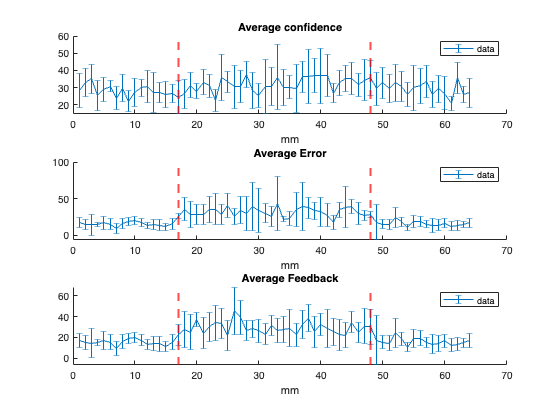

xline(17,'r--','LineWidth',2,'HandleVisibility','off');
xline(48,'r--','LineWidth',2,'HandleVisibility','off');
xlabel('mm')
title('Average Feedback')

%Centered endpoints when perturbation is on or off. 
% 
% figure
% for ii = 1:6
%     x = ptbOrder == ii;
%     s = sessions(x);
%     p1 = [endPtsShift(17+s:48+s,:);endPtsShift(17+s:48+s,:)];                         % First Point
%     r1 = [endPtsShift([s+1:s+10,s+55:s+64],:);endPtsShift([s+1:s+10,s+55:s+64],:)];
% 
%     subplot(2,3,ii); hold on
%     scatter(p1(:,1),p1(:,2))
%     scatter(r1(:,1),r1(:,2))
%     grid
%     legend('on','off')
%     xlim([-80 80])
%     ylim([-80 80])
%     xticks([-80 0 80])
%     yticks([-80 0 80])
%     title(ptbType(ptbOrder(ii)))
%     axis square
% 
% end


%Hand angle change
start = [0 -100];
figure
for ii = 1:2
    x = ptbOrder == ii;
    s = sessions(x);
    p1 = endPtsShift(1+s:64+s,:); 
 
    a = sqrt((p1(:,1) - 0).^2 + (p1(:,2)-0).^2);
    b = sqrt((p1(:,1) - start(:,1)).^2 + (p1(:,2)-start(:,2)).^2);
    c = sqrt((start(:,1) - 0).^2 + (start(:,2)-0).^2); 

    cosTheta = (b.^2+c^2-a.^2)./(2*b*c);
    theta = real(acosd(cosTheta));
    theta(p1(:,1) <0) = theta(p1(:,1) <0)*-1;
    
    subplot(2,1,ii); hold on
    plot(theta)
    xline(17,'--');
    xline(48,'--');
    ylabel('hand angle deg')
    xlabel('trial')
    yline(0);
end 

Unrecognized function or variable 'endPtsShift'.